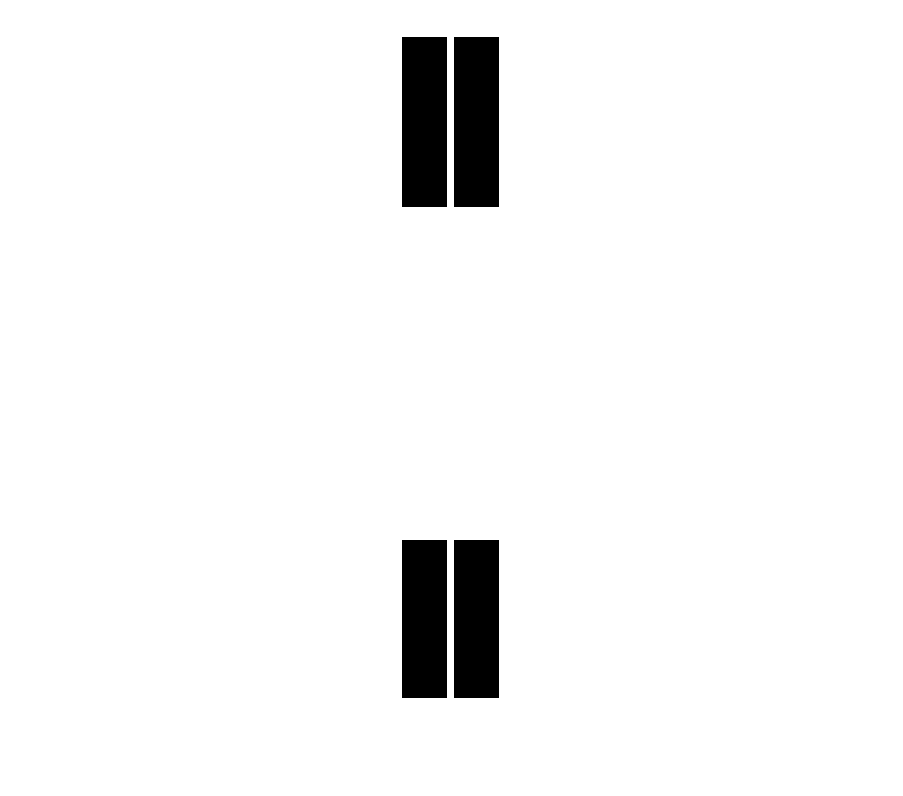

clear all;
close all;
clc;

%Zoom Exercise
T = im2double(imread('florida-interference.tif')); 
%T = 600x800 pixels
M = size(T,1);
N = size(T,2);
dist = zeros(M,N);
filter = ones(M,N);

filter(1:1:170,290:1:334) = 0;
filter(1:1:170,342:1:386) = 0;
filter(505:1:662,290:1:334) = 0;
filter(505:1:662,342:1:386) = 0;

imshow(filter);

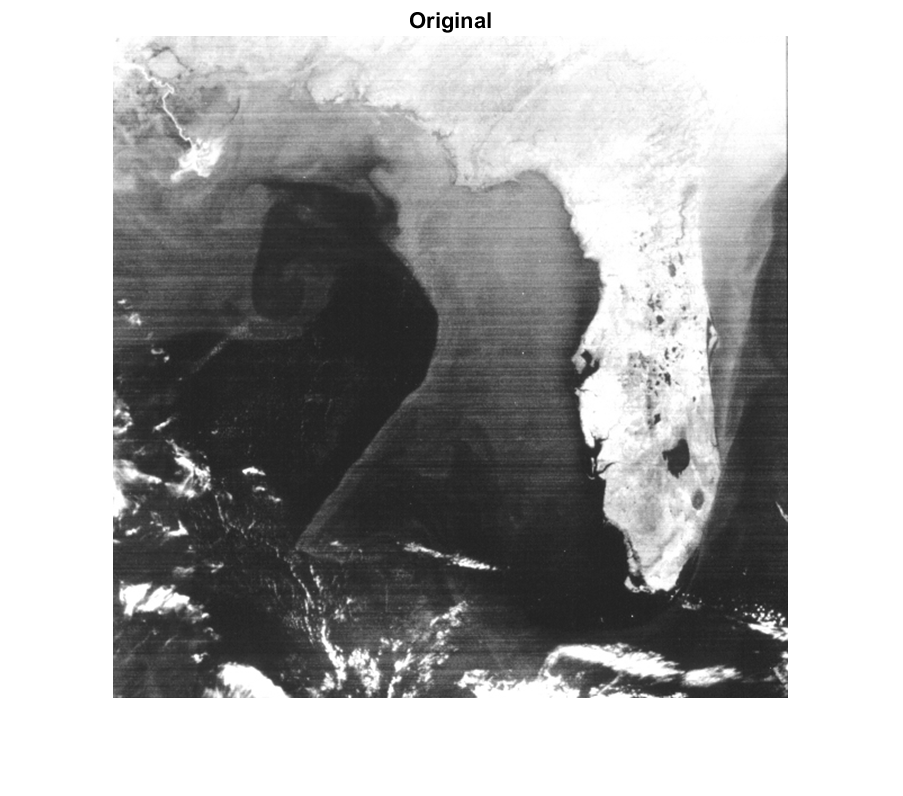


imshow(T); title('Original');

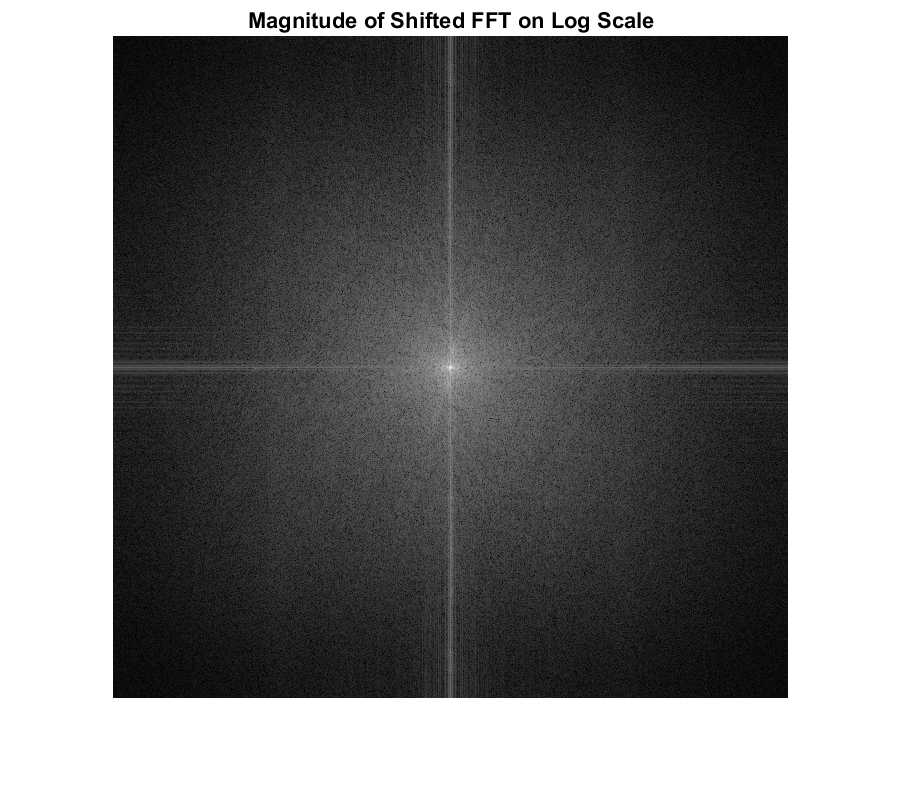


TZfft = fft2(T);
TZfft2 = fftshift(TZfft);

TZfft3 = log(abs(TZfft2)+1); %abs and + 1 for display
disp_fft = mat2gray(TZfft3); 
imshow(disp_fft); title('Magnitude of Shifted FFT on Log Scale');

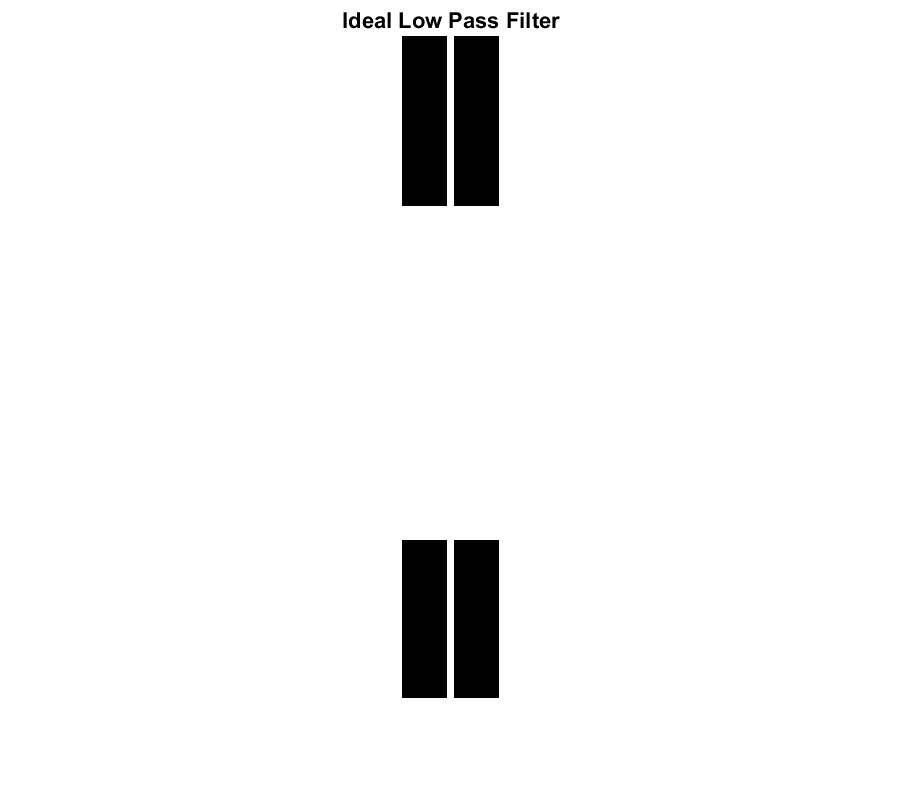


imshow(filter); title('Ideal Low Pass Filter');

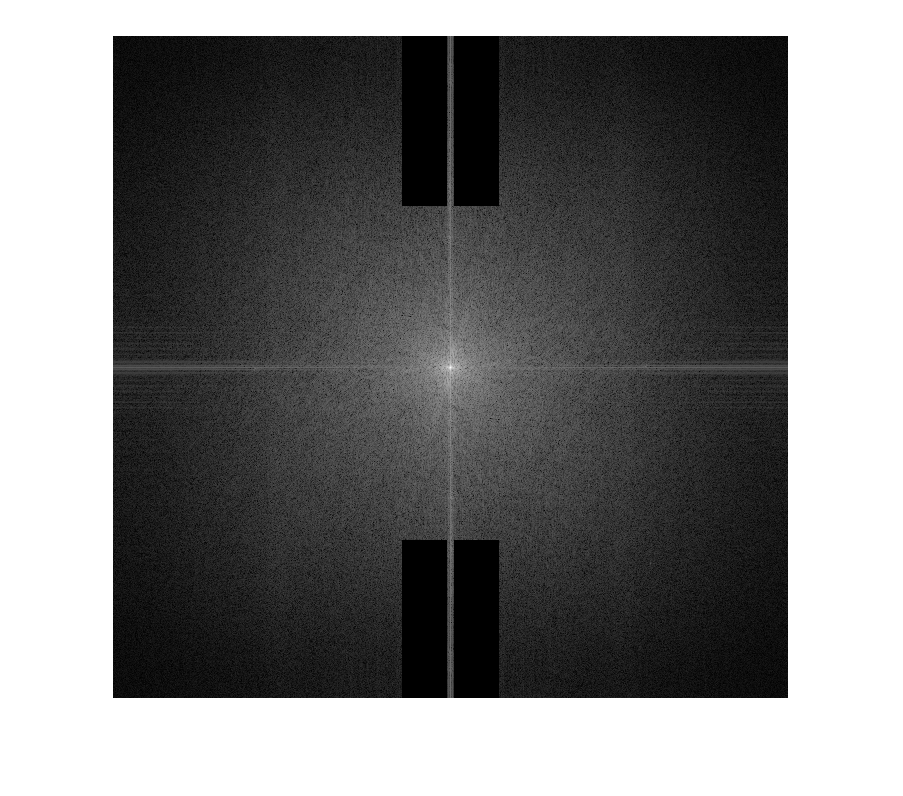


Tlp = TZfft2 .* filter;
mod = log(abs(Tlp)+1);
imshow(mat2gray(mod));

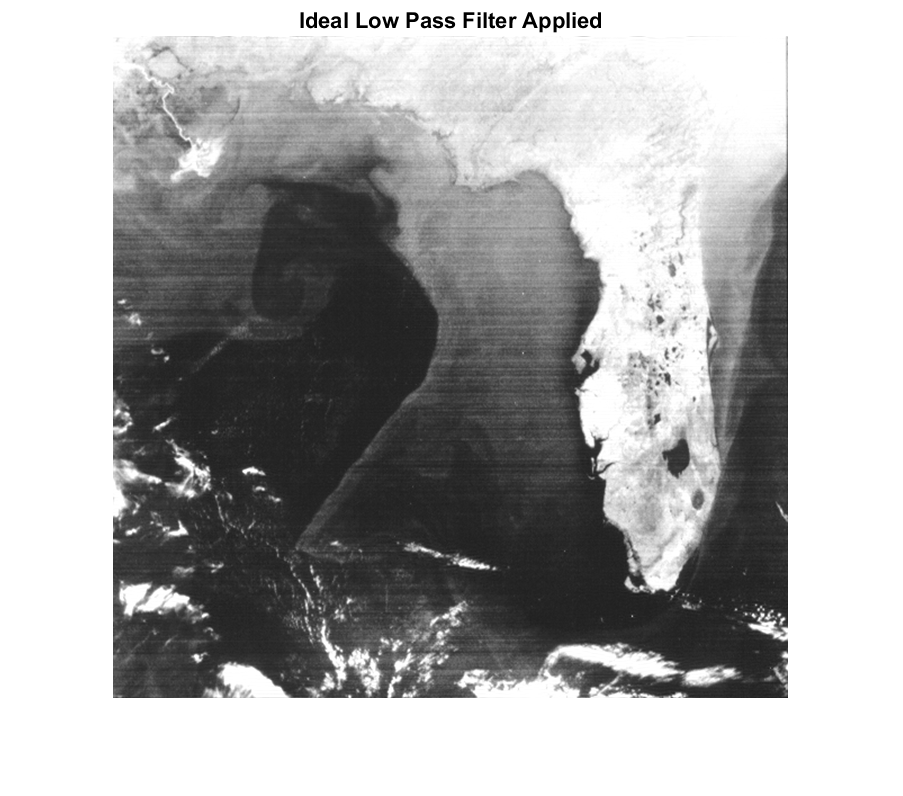

Tlp2 = ifftshift(Tlp);
Tlp3 = abs(ifft2(Tlp2));
TLowPass = Tlp3(1:M,1:N);
imshow(TLowPass); title('Ideal Low Pass Filter Applied');